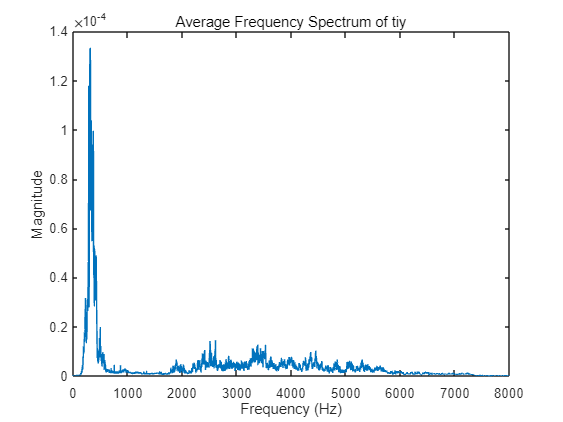

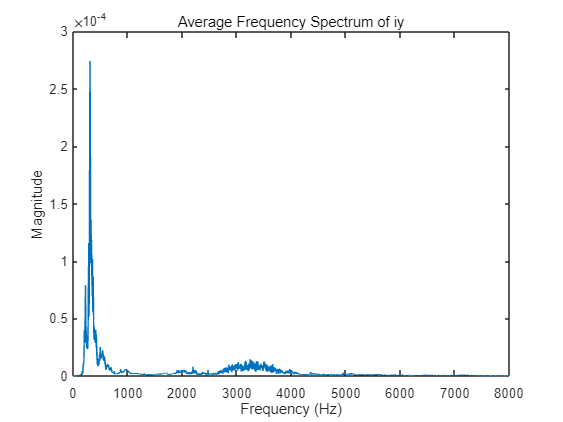

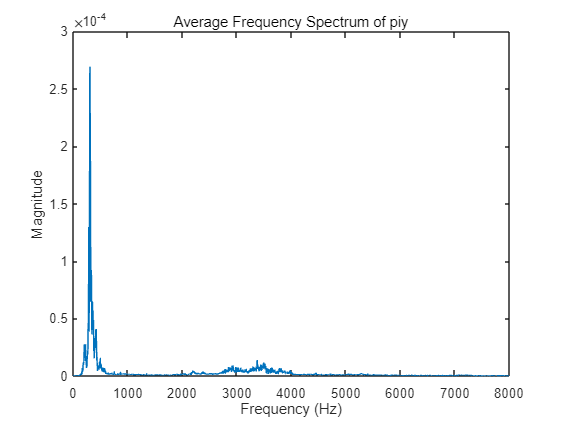

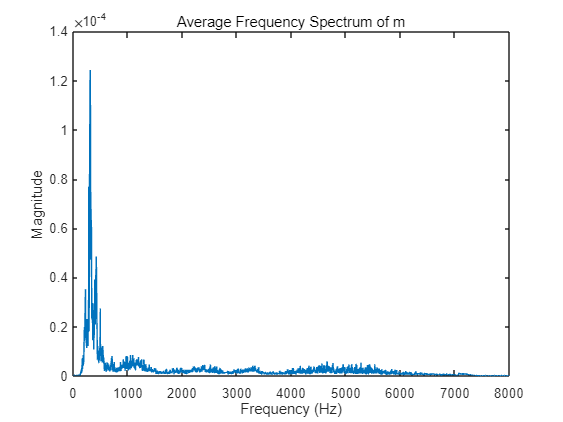

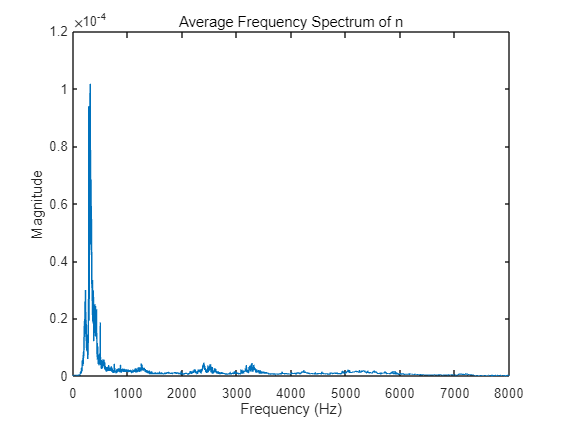

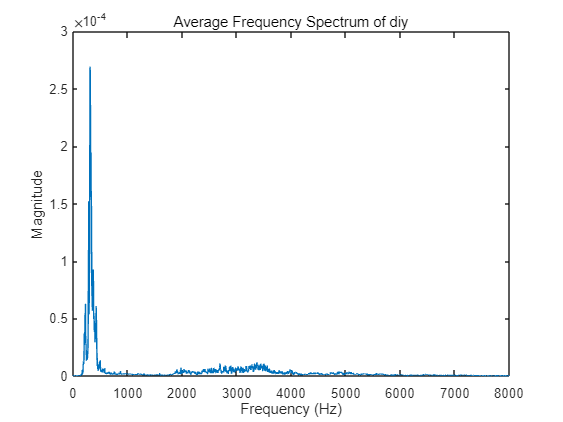

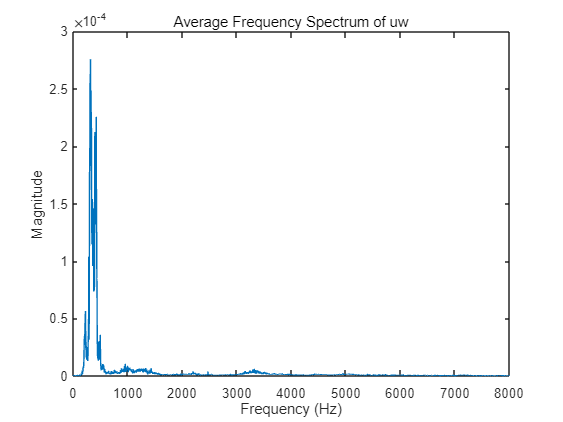

clear; close all; clc;

base_path = 'D:\W00Y0NG\PRGM2\MATLAB\2023mathFFT\MM18\kinect_data\';

% 각 음운별 파일 번호 리스트
phoneme_files = {
    'tiy', [0, 3, 5, 13, 17, 18, 23, 49, 58, 69, 76, 78],  
    'iy',  [1, 32, 40, 42, 44, 53, 57, 63, 67, 70, 74, 79],
    'piy', [2, 12, 19, 20, 25, 30, 33, 38, 39, 41, 68, 83],
    'm',   [4, 6, 10, 21, 24, 27, 28, 35, 36, 43, 54, 64],
    'n',   [7, 11, 15, 16, 22, 29, 37, 47, 55, 65, 72, 82],
    'diy', [8, 9, 14, 46, 48, 50, 52, 59, 62, 71, 73, 77],
    'uw',  [26, 31, 34, 45, 51, 56, 60, 61, 66, 75, 80, 81]
};

% 결과를 저장할 구조체 초기화
phonemeSpectrums = struct();

% 샘플링 레이트 및 샘플 비트 깊이 확인
Fs = 44100; % 샘플링 레이트
bytesPerSample = 2; % 16비트 = 2바이트
bitsPerSample = 16; % 16비트 오디오

% 55KB를 샘플 수로 변환
targetBytes = 55 * 1024; % 55KB
targetSamples = targetBytes / bytesPerSample; % 샘플 수

% 각 음운별로 평균 스펙트럼 계산
for i = 1:size(phoneme_files, 1)
    phoneme = phoneme_files{i, 1};
    fileIndices = phoneme_files{i, 2};
    
    % FFT 결과를 저장할 배열의 크기를 미리 할당
    % 첫 번째 파일 읽어서 FFT 결과 크기를 얻기
    filename = fullfile(base_path, sprintf('%d.wav', fileIndices(1)));
    [y, Fs] = audioread(filename);
    Y = fft(y, targetSamples);
    P2 = abs(Y/targetSamples);
    P1 = P2(1:targetSamples/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    L = length(P1); % FFT 결과 길이
    
    % phonemeFFTResults 배열 사전 할당
    phonemeFFTResults = zeros(length(fileIndices), L);
    
    for j = 1:length(fileIndices)
        % 파일 이름 생성
        filename = fullfile(base_path, sprintf('%d.wav', fileIndices(j)));
        
        % 오디오 파일 읽기
        [y, Fs] = audioread(filename);
        
        % 파일 길이를 targetSamples에 맞추기
        if length(y) > targetSamples
            % 파일이 너무 길면, targetSamples까지 잘라내기
            y = y(1:targetSamples);
        elseif length(y) < targetSamples
            % 파일이 너무 짧으면, targetSamples 길이가 되도록 뒤에 0을 추가
            y = [y; zeros(targetSamples - length(y), 1)];
        end
        
        % FFT 수행
        Y = fft(y, targetSamples);
        
        % 단방향 스펙트럼 계산
        P2 = abs(Y/targetSamples);
        P1 = P2(1:targetSamples/2+1);
        P1(2:end-1) = 2*P1(2:end-1);
        
        % 결과를 배열에 저장
        phonemeFFTResults(j, :) = P1';
    end
    
    % 평균 스펙트럼 계산
    averageSpectrum = mean(phonemeFFTResults, 1);
    
    % 주파수 축 생성
    f = Fs*(0:(L-1))/targetSamples;
    
    % 구조체에 저장
    phonemeSpectrums.(phoneme) = struct('f', f, 'averageSpectrum', averageSpectrum);
    
    % 평균 스펙트럼 시각화
    figure;
    plot(f, averageSpectrum);
    title(['Average Frequency Spectrum of ', phoneme]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    
    % 평균 스펙트럼을 파일로 저장
    filename = sprintf('avg_spectrum_%s.mat', phoneme);
    save(filename, 'f', 'averageSpectrum');
end